# 1.3.02 Программирование. Цикл FOR

Приведенный ниже код строит конус второго порядка с параметрами `a`, `b` и `с`, который описывается уравнением:


$$\begin{cases} 
\begin{array}{l}
\frac{x^2 }{\frac{a^2 h^2 }{c^2 }}+\frac{y^2 }{\frac{a^2 h^2 }{c^2 }}=1\\
z=h
\end{array}
\end{cases}$$


Конус строится с помощью функции `surf()`, и в результате построения имеем описание поверхности конуса в переменной `hCone`. 

Функция `rotate()` поворачивает объекты в заданном направлении и на заданную величину. Например, повернуть конус на $1^o$можно следующим образом:

Используя конструкции `for-end` поворачивайте конус с шагом в $1^o$ вокруг оси `x`, затем вокруг `y`, затем вокруг `z`. Выводите текущий угол поворота в подписях по осям `x`, `y` и `z` соответственно. Замедлить анимацию можно командой `pause(0.01)`.

% задание параметров и высоты конуса
a = 1; b = 1; c = 1.5;
h = [-2:0.1:2];
% задание количества граней
theta = [0:pi/20:2*pi]';
% расчет параметров
a1=sqrt(a^2*h.^2/c^2);
b1=sqrt(b^2*h.^2/c^2);
x = cos(theta)*a1;
y = sin(theta)*b1;
z = ones(size(theta))*h;
figure('NumberTitle','off',...
    'Name','Конус второго порядка',...
    'Color','w',...
    'Visible','on')
% построение конуса
hCone=surf(x,y,z)

hCone =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [41×41 double]
           YData: [41×41 double]
           ZData: [41×41 double]
           CData: [41×41 double]

  Show all properties


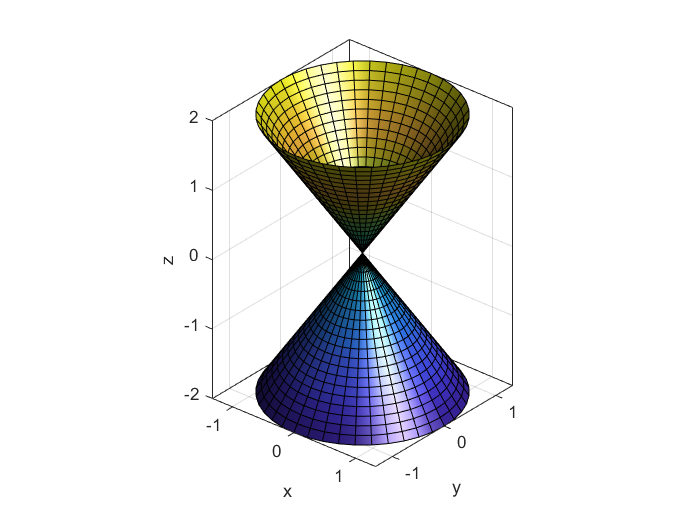

xlabel('x'),ylabel('y'),zlabel('z')
axis equal, box on
% настройки освещения
light, lighting gouraud
% задание точки обзора
view(40,30)

## Поворот конуса

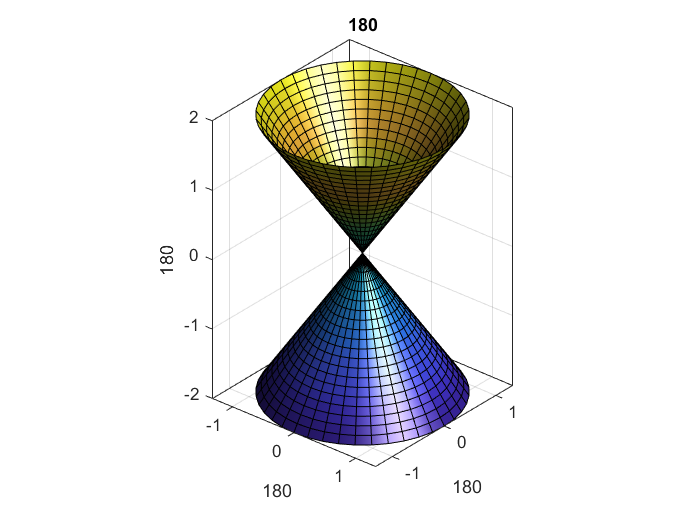

for k=[0 0 1;0 1 0;1 0 0]
    for n =1:180
        title(n)
        rotate(hCone, k, 1);
        pause(0.01)
        
        if k' == [1 0 0]
            xlabel(n);
        elseif k' == [0 1 0]
            ylabel(n)
        elseif k' ==[0 0 1]
            zlabel(n)
        end
    end
end